## Lab 3

First import Quanser set of data

clear all;clc;
QuanserData;

### Question 1, 2, 3, 4

paper

### Question 5

Open the Simulink model

open('Electrical_sol.slx')

Find the equilibrium point for a constant input V=10V. (function trim)

Set initial values (or not: in that case use [ ] )

%x0=[];u0=[];y0=[];
x0=[];
u0=10;%Initial input at 10
y0=[]; 

Select the index of states and/or states which are to be freezed:

ix=[];
iu=1; %The input n°1 is set constant initial value was set at 10
iy=[];

Find the equilibrium point:

[xtrim,utrim,ytrim,dxtrim] = trim('Electrical_sol',x0,u0,y0,ix,iu,iy)

xtrim =   224.4221
    0.0684


utrim = 10

ytrim =     0.0191
  224.4221
    0.0684


dxtrim = 	1.0e+-8 *

   -0.0004
   -0.1584


### Question 6

Find the linearized model at the equilibrium point. (function linmod)

[A,B,C,D] = linmod('Electrical_sol', xtrim, utrim)

A = 	1.0e+03 *

   -0.0012    3.7490
   -0.0362   -7.2414


B =          0
  862.0690


C =     0.0003         0
    1.0000         0
         0    1.0000


D =      0
     0
     0


Create a state space model and a transfer function model

Gss=ss(A,B,C,D);
Gss=Gss(1,1);
Gtf=tf(Gss)


Gtf =
 
            843
  -----------------------
  s^2 + 7243 s + 1.445e05
 
Continuous-time transfer function.



damp(Gtf)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -2.00e+01     1.00e+00       2.00e+01         5.00e-02    
 -7.22e+03     1.00e+00       7.22e+03         1.38e-04    


### Question 7

compare with question 3. You must have a perfect fit since the states are the same

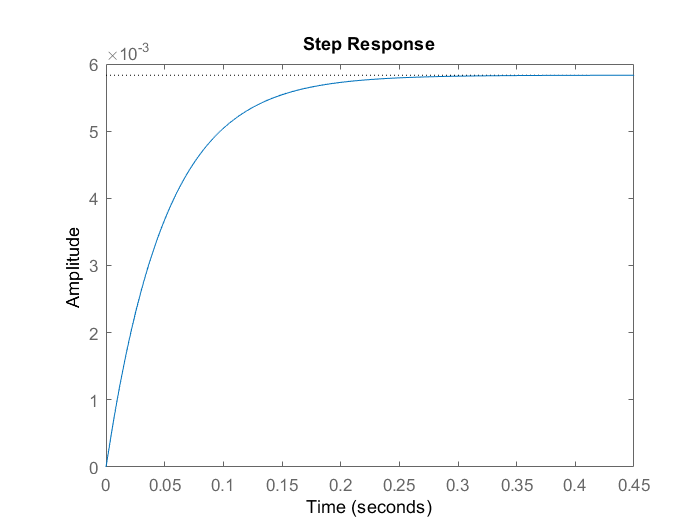

step(Gtf)

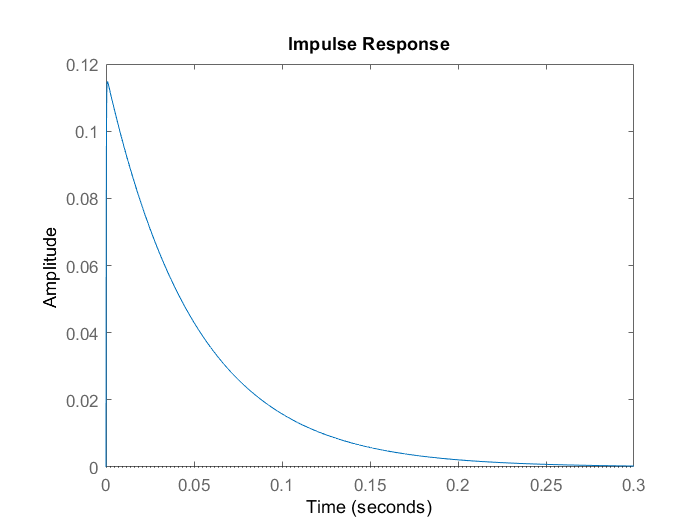

impulse(Gtf)

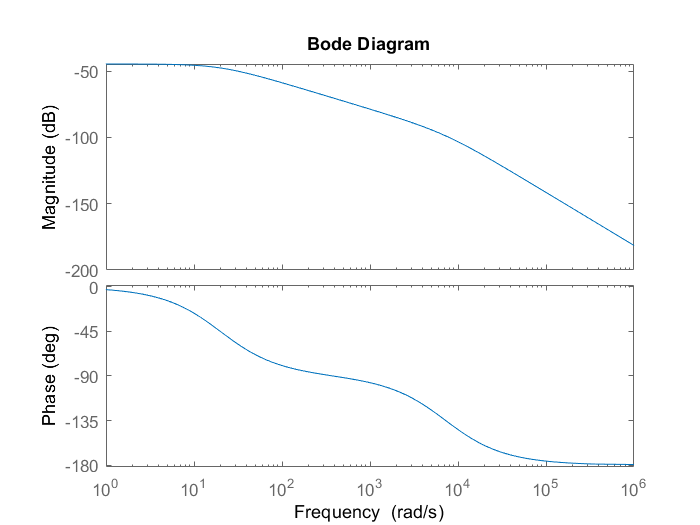

bode(Gtf)

pole(Gtf) %which mode is dominant? (compare with Rm/Lm !!)

ans = 	1.0e+03 *

   -7.2226
   -0.0200


### Question 8

Create the full simulation model Mechanical.slx

open('Mechanical_sol.slx')

Extract and examine the state structure of the model:

x = Simulink.BlockDiagram.getInitialState('Mechanical_sol')

x = Simulink.SimulationData.Dataset 'xFinal' with 6 elements

                        Name  BlockPath                         
                        ____  _________________________________ 
    1  [1x1 State]      ''    Mechanical_sol/Integrator        
    2  [1x1 State]      ''    Mechanical_sol/Integrator1       
    3  [1x1 State]      ''    Mechanical_sol/Motor1/Integrator 
    4  [1x1 State]      ''    Mechanical_sol/Motor1/Integrator1
    5  [1x1 State]      ''    Mechanical_sol/Motor2/Integrator 
    6  [1x1 State]      ''    Mechanical_sol/Motor2/Integrator1

  - Use braces { } to access, modify, or add elements using index.


### Question 9

Find the equilibrium point:

x0=[];
u0=0;%Input is initialized at 0V
y0=[]; 
ix=[];
iu=1; %Input 1 is freezed
iy=[];
[xtrim,utrim,ytrim,dxtrim] = trim('Mechanical_sol',x0,u0,y0,ix,iu,iy)

xtrim =     0.0000
  224.4221
  224.4221
   -0.0000
    0.0684
    0.0684


utrim = -2.6470e-22

ytrim = 7.9317e-19

dxtrim = 	1.0e+-10 *

   -0.0000
   -0.0414
   -0.0414
   -0.0000
   -0.3187
   -0.3187


The system is of order 6 (two states for each motors and two states more for the pendulum)

### Question 10

Find the linearized model

[A,B,C,D] = linmod('Mechanical_sol', xtrim, utrim)

A = 	1.0e+03 *

         0         0         0    0.0010         0         0
         0   -0.0012         0         0    3.7490         0
         0         0   -0.0012         0         0    3.7490
   -0.0037    0.0000   -0.0000   -0.0003         0         0
         0   -0.0362         0         0   -7.2414         0
         0         0   -0.0362         0         0   -7.2414


B =          0
         0
         0
         0
  862.0690
 -862.0690


C =      1     0     0     0     0     0


D = 0

Gmec=ss(A,B,C,D)


Gmec =
 
  A = 
              x1         x2         x3         x4         x5         x6
   x1          0          0          0          1          0          0
   x2          0     -1.213          0          0       3749          0
   x3          0          0     -1.213          0          0       3749
   x4     -3.726   0.001917  -0.001917    -0.3302          0          0
   x5          0     -36.21          0          0      -7241          0
   x6          0          0     -36.21          0          0      -7241
 
  B = 
           u1
   x1       0
   x2       0
   x3       0
   x4       0
   x5   862.1
   x6  -862.1
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



### Question 11

Compute controlability/observability matrix

Co = ctrb(A,B);
Ob = obsv(A,C);

Determine the number of uncontrollable/unobservable states.

unco = length(A) - rank(Co)

unco = 4

unob = length(A) - rank(Ob)

unob = 2

Look at the poles and zeros:

zpk(Gmec)


ans =
 
             12390 (s+20.01) (s+7223)
  ----------------------------------------------
  (s+20.01)^2 (s+7223)^2 (s^2 + 0.3302s + 3.726)
 
Continuous-time zero/pole/gain model.



We see that two zeros are cancelled by two poles. There are consequently two uncontrolable/unobservable poles, this is not consistent with the rank calculated above. The reason is that the **rank** function compares the relative magnitude of each singular values. One singular value being almost infinite, the automatic criteria is too high. You must relax this criteria by setting an appropriate tolerance: 

tol=1e-6;
unco = length(A) - rank(Co,tol)

unco = 2

unob = length(A) - rank(Ob,tol)

unob = 2

### Question 12

Use minreal to obtain the pole-zero cancelled transfer function

Gmec_reduced=minreal(Gmec)
zpk(Gmec_reduced)
step(Gmec,Gmec_reduced,20)